# 时间最优（测试）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 200.; % s
% x0 = [2200., 8000., 1000., 0., 0., 0.]';  % km, km/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 0.01; % s
p.f = 0.01; % N/kg; m/s^2

### 反向推力

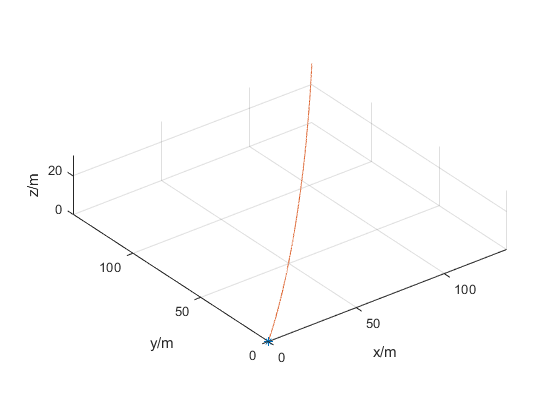

[t, x] = ode45(@(t, x) CwEq(t, x, [0.5, 0.4, 0.1] / norm([0.5, 0.4, 0.1]) * p.f, p), tf - (0 : p.tspan : tf), xf);
s = [t, x];
x0 = x(end, :)';
figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

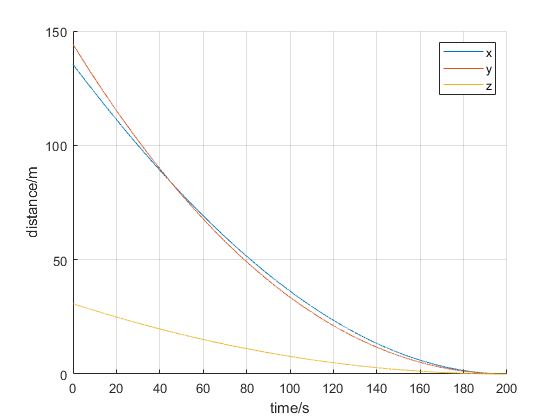

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

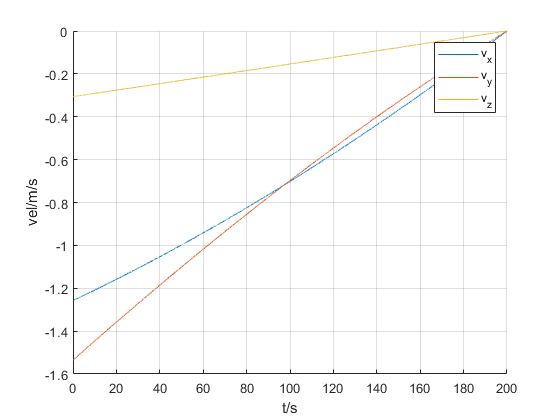

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    2.000000e+02    1.193e+03    1.000e+00
    1      16    1.990021e+02    1.194e+03    9.999e-01    1.472e+00
    2      26    1.967341e+02    1.579e+03    1.000e+00    2.565e+00
    3      34    1.705565e+02    1.192e+03    9.999e-01    2.618e+01
    4      42    8.627327e-01    1.429e+02    4.937e-01    1.697e+02
    5      52    5.537056e+01    1.408e+02    5.790e-01    5.451e+01
    6      62    5.868407e+01    1.628e+02    5.790e-01    3.322e+00
    7      70    5.806710e+01    1.422e+02    5.790e-01    6.370e-01
    8      79    6.119305e+01    1.155e+02    5.790e-01    3.128e+00
    9      87    5.477685e+01    6.353e+01    5.790e-01    6.416e+00
   10      97    4.351378e+01    2.351e+01    5.790e-01    1.126e+01
   11     106    4.185483e+01    2.085e+01    5.790e-01    1.661e+00
   12     119    4.184548e+01    2.067e+01    5

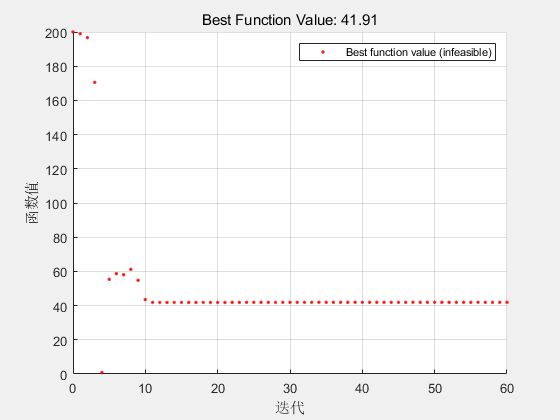


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptTime3(@(t, x) CwTimeOpt2(t, x, p), x0, xf, tf, p);

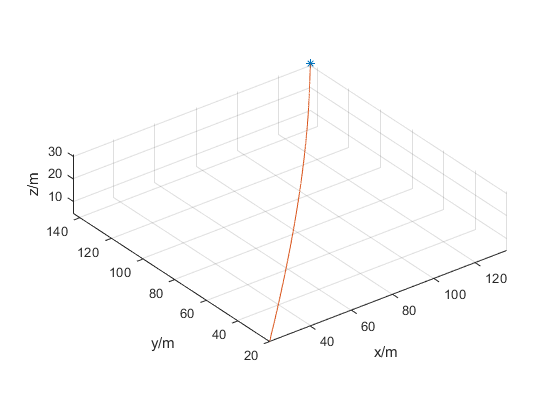

% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p);
figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

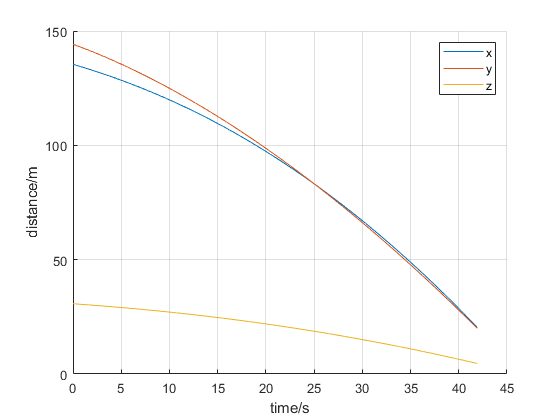

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

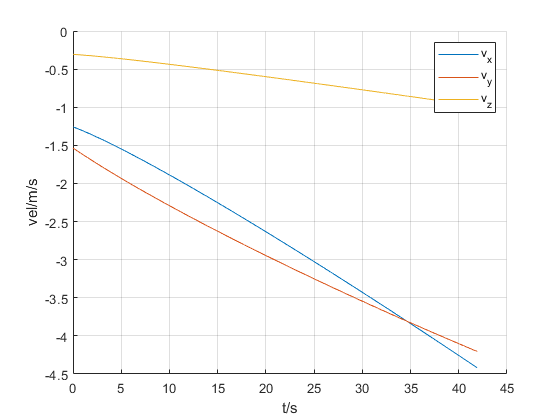

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

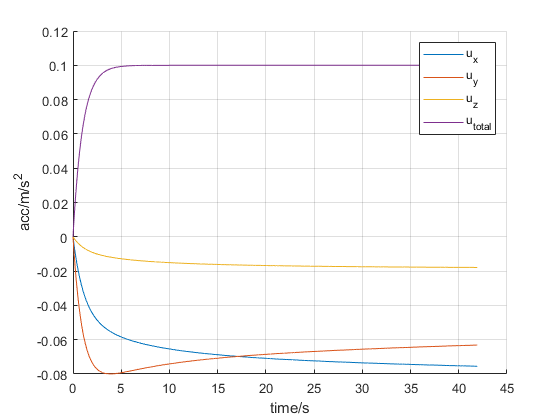

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off